# CME192 Assignment 2, Part 1: Unsupervised and Supervised Machine Learning

In this assignment, we analyze the UCI Vertebral Column dataset, which contains six biomechanical measurements of the spine along with a clinical class label. Our objective is to understand the structure of the data using both unsupervised and supervised machine learning techniques.

The UCI Vertebral Column dataset comes from the UCI Machine Learning Repository, a widely used collection of benchmark datasets for teaching and research in machine learning. It contains six quantitative biomechanical measurements of the spine derived from radiographic analysis. Each observation is labeled as one of three clinical categories: DH (Disk Hernia), SL (Spondylolisthesis), or NO (Normal). The dataset is commonly used to study classification, clustering, and dimensionality reduction methods because it combines real clinical structure with measurable overlap between classes.

We begin by exploring relationships among the raw features and examining their correlation structure. We then apply dimensionality reduction and clustering to study the geometry of the data without using labels. Finally, we train and evaluate supervised classifiers to assess how well the clinical classes can be predicted.

This dataset is used for machine learning instruction only and is not intended for clinical decision-making.

## Part A: Data loading + initial plots (already done)

close all; clear; clc
rng(0)

dataFile = "vertebral_column_3C.csv";
assert(isfile(dataFile), "Could not find %s. Put it in your current folder.", dataFile)

data = readtable(dataFile);

% Class labels are categorical: DH, SL, NO
data.class = categorical(data.class);

% Match the schema: first 6 columns are numeric features
labels = data.Properties.VariableNames(1:6);
stats = data{:,1:6};
VCtrue = data.class;

data(1:8,:)

ans = 8×7 table
    pelvic_incidence    pelvic_tilt    lumbar_lordosis_angle    sacral_slope    pelvic_radius    degree_spondylolisthesis    class
    ________________    ___________    _____________________    ____________    _____________    ________________________    _____

         63.03             22.55               39.61               40.48            98.67                  -0.25              DH  
         39.06             10.06               25.02                  29           114.41                   4.56              DH  
         68.83             22.22               50.09               46.61           105.99                  -3.53              DH  
          69.3             24.65               44.31               44.64           101.87 

summary(data)


data: 310×7 table

Variables:

    pelvic_incidence: double
    pelvic_tilt: double
    lumbar_lordosis_angle: double
    sacral_slope: double
    pelvic_radius: double
    degree_spondylolisthesis: double
    class: categorical (3 categories)

Statistics for applicable variables:

                                NumMissing        Min            Median           Max             Mean            Std    

    pelvic_incidenc

tabulate(VCtrue)

  Value    Count   Percent
     DH       60     19.35%
     NO      100     32.26%
     SL      150     48.39%


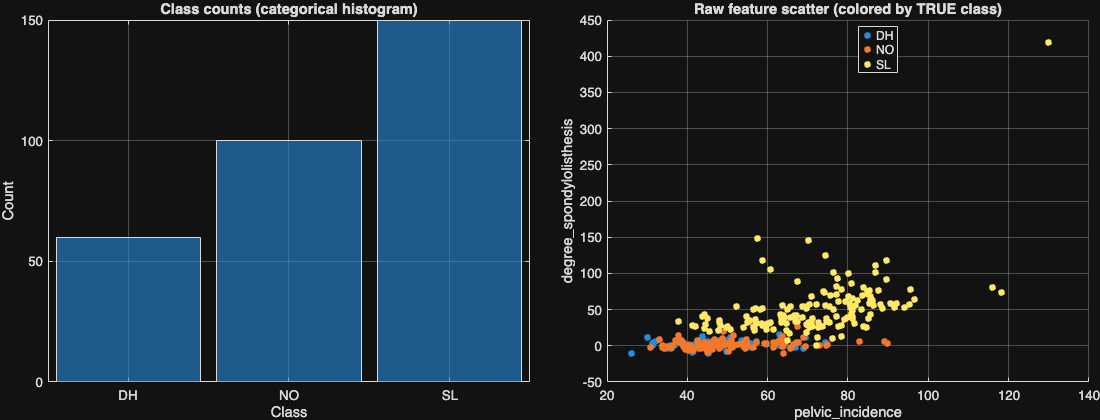


% Plot 1: class counts (expect class imbalance)
% Plot 2: a simple 2D scatter of two raw features (colored by TRUE class)
f0 = newFig("Part A: Quick look", [1100 420]);
tl = tiledlayout(f0, 1, 2, "TileSpacing","compact");
tl.Padding = "tight";

nexttile;
histogram(VCtrue);
grid on
title("Class counts (categorical histogram)", "FontWeight","bold")
xlabel("Class"); ylabel("Count")

nexttile;
xFeat = data.pelvic_incidence;
yFeat = data.degree_spondylolisthesis;
gscatter(xFeat, yFeat, VCtrue);
grid on
xlabel("pelvic_incidence", "Interpreter","none")
ylabel("degree_spondylolisthesis", "Interpreter","none")
title("Raw feature scatter (colored by TRUE class)", "FontWeight","bold")

## Part B: Correlation heatmap + normalization (6 pts)

In this step, we examine how the features relate to one another. The correlation heatmap helps us see which measurements tend to increase or decrease together, revealing underlying structure in the data. We then normalize the features so they are on a comparable scale, which is essential for methods like PCA, k-means, kNN, and SVM that depend on distances or variance.

% TODO: Compute the correlation matrix of the stats array.
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Unsupervised Learning  ->
% "correlation heatmap". We used the `corr` function here!
R = _________________________;
f2 = newFig("Part B: Correlation heatmap", [820 650]);
h = heatmap(R, 'Colormap', parula);
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
h.Title = "Feature correlation (Pearson r)";
% What to expect:
% - A 6x6 heatmap
% - Darker/stronger colors indicate stronger correlation (positive or negative)

% TODO: Normalize numeric features to mean 0 and standard deviation 1.
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Unsupervised Learning  ->
% "normalize data". We used the `normalize` function here!
statsNorm = ______________________;

muRaw = mean(stats, 1);
sigRaw = std(stats, 0, 1);

muN = mean(statsNorm, 1);
sigN = std(statsNorm, 0, 1);

disp(table(labels', muRaw', sigRaw', muN', sigN', ...
    'VariableNames', ["Feature","MeanRaw","StdRaw","MeanNorm","StdNorm"]))
% What to expect: mean should be close to 0 and std dev should be close to
% 1. 

## Part C: Unsupervised PCA (4 pts)

In this step, we use Principal Component Analysis (PCA) to identify the main directions of variability in the normalized data. Recall that PCA constructs new orthogonal axes (principal components) that capture as much variance as possible in descending order. We primarily use the first two components to visualize the data and assess whether the classes show any natural separation.

% TODO: Run PCA on the normalized features (statsNorm).
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Principal Component Analysis (PCA)
[pcs,scrs,~,~,pexp] = ________________________________;

f3 = newFig("Part C: PCA explained variance", [700 520]);
pareto(pexp)
xlabel("Principal Component")
ylabel("Variance Explained (%)")
title("PCA explained variance (pareto)")

f4 = newFig("Part C: PCA scatter", [720 560]);
gscatter(scrs(:,1), scrs(:,2), VCtrue);
grid on
xlabel("PC1"); ylabel("PC2");
title("PCA scores (PC1 vs PC2), colored by TRUE class", "FontWeight","bold")

% What to expect:
% - PC1 explains the most variance, then PC2, etc.
% - Classes may show some separation, but overlap is normal.

## Part D: Unsupervised k-means clustering (4 pts)

In this step, we apply k-means to the normalized data to partition the observations into K=3 clusters, matching the number of clinical classes. 

Importantly, k-means does not use the labels and has no knowledge of DH, SL, or NO. It simply groups points based on geometric similarity in feature space. 

The cluster numbers themselves are arbitrary and may change between runs, so the focus should be on the composition of each cluster rather than the numeric ID. If one class dominates a cluster, it suggests some geometric separation; if clusters are mixed, it indicates overlap between classes.

k = 3;

% TODO: Run k-means clustering on normalized features (statsNorm).
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Unsupervised Learning  ->  "Perform k-means clustering"
grpKM = ________________________________;


%% D1) Silhouette plot (how well-separated are the clusters?)
% What to expect:
% - Values close to 1: points are well matched to their cluster
% - Values near 0: overlapping clusters (common in real data)
% - Negative values: possible mis-clustering for those points
f5 = newFig("Part D: k-means silhouette", [780 520]);
silhouette(statsNorm, grpKM);
title("Silhouette plot (k-means, K=3)", "FontWeight","bold");

%% D2) Compare cluster IDs to TRUE class (stacked bar chart)
% What to expect:
% - Each bar is a cluster (1,2,3).
% - Bar segments show how many DH/NO/SL points ended up in that cluster.
% - "Pure" clusters would have mostly one color segment.
% - Mixed clusters indicate overlap between classes in feature space.
clusterID = categorical(grpKM);
trueCats = categories(VCtrue);
clustCats = categories(clusterID);
T = crosstab(clusterID, VCtrue);
f6 = newFig("Part D: Cluster composition (counts)", [820 520]);
bar(T, "stacked");
grid on
xlabel("Cluster ID (k-means)");
ylabel("Number of samples");
title("Cluster composition by TRUE class (counts)");

ax = gca;
ax.XTick = 1:numel(clustCats);
ax.XTickLabel = clustCats;

legend(trueCats, "Location","eastoutside");

## Part E: kNN classifier (8 pts)

In this step, we move to supervised learning and use the class labels to train a k-nearest neighbors (kNN) classifier. We split the data into training and test sets using a holdout partition, fit the model on the training data, and evaluate performance on the unseen test set. The confusion chart and accuracy provide a quantitative measure of how well the model predicts the clinical classes.

vcTbl = array2table(statsNorm, 'VariableNames', labels);
vcTbl.class = VCtrue;

pt = cvpartition(vcTbl.class, "Holdout", 0.25);

% TODO: Determine training and test indices (lecture uses training(pt) and ~training(pt))
idxTrain = ________________________________;
idxTest = ________________________________;

trainTbl = vcTbl(idxTrain,:);
testTbl = vcTbl(idxTest,:);

% TODO: Fit a kNN model
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Classification  ->  kNN. We
% used `fitcknn` in lecture. 
mdlKNN = ________(__________, "class");
mdlKNN.NumNeighbors = 5;

% TODO: Predict on the test set
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Classification  ->  predict + confusionchart
knnPred = ________(________, testTbl);

f7 = newFig("Part E: kNN confusion chart", [760 560]);
confusionchart(testTbl.class, knnPred);
title("kNN test-set performance", "FontWeight","bold")

knnAcc = mean(knnPred == testTbl.class);
fprintf("kNN test accuracy = %.3f\n", knnAcc)

## Part F: SVM (ECOC) classifier (8 pts)

In this step, we fit another supervised model: an SVM-based multiclass classifier (ECOC). This is a common baseline for small numeric datasets.

% TODO: Create an SVM template (Gaussian / RBF kernel)
% Hint: Lecture_05_a_UnsupervisedML.mlx  ->  Classification  ->  Multiclass SVM
template = _______________("KernelFunction","gaussian");

% TODO: Fit ECOC multiclass model using the SVM learner
mdlSVM = __________(trainTbl, "class", "Learners", template);

% TODO: Predict on the test set
svmPred = _______(______, testTbl);

f8 = newFig("Part F: SVM confusion chart", [760 560]);
confusionchart(testTbl.class, svmPred);
title("SVM (Gaussian) test-set performance", "FontWeight","bold")

svmAcc = mean(svmPred == testTbl.class);
fprintf("SVM test accuracy = %.3f\n", svmAcc)

results = table([knnAcc; svmAcc], 'VariableNames', "TestAccuracy", ...
    'RowNames', ["kNN" "SVM (gaussian)"]);
disp(results)

f9 = newFig("Part F: Misclassified test points (PCA space)", [1100 460]);
tl = tiledlayout(f9, 1, 2, "TileSpacing","compact");
tl.Padding = "tight";

nexttile;
gscatter(scrs(idxTest,1), scrs(idxTest,2), testTbl.class);
hold on
testScores = scrs(idxTest,:);
plot(testScores(knnPred ~= testTbl.class, 1), testScores(knnPred ~= testTbl.class, 2), ...
    "ko", "LineWidth", 1.5, "MarkerSize", 7);
grid on
xlabel("PC1"); ylabel("PC2");
title("kNN: misclassified test points (black circles)", "FontWeight","bold")
legend("Location","bestoutside")

nexttile;
gscatter(scrs(idxTest,1), scrs(idxTest,2), testTbl.class);
hold on
testScores = scrs(idxTest,:);
plot(testScores(svmPred ~= testTbl.class, 1), testScores(svmPred ~= testTbl.class, 2), ...
    "ko", "LineWidth", 1.5, "MarkerSize", 7);
grid on
xlabel("PC1"); ylabel("PC2");
title("SVM: misclassified test points (black circles)", "FontWeight","bold")
legend("Location","bestoutside")

% What to expect:
% - Misclassified points typically appear near overlapping regions in PCA space.
% - If one model is better, it should have fewer black circles.

## Helper function (provided)

function f = newFig(figName, sz)
    if nargin < 2, sz = [980 520]; end
    f = figure("Name", figName, "Units","pixels", ...
        "Position",[80 80 sz(1) sz(2)]);
end